Question5 

(c)  Write a function $\mathrm{rosenbluthsamplingSAW}\left(N\right)$to use Rosenbluth sampling to estimate the number of self-avoiding walks of length $1\ldotp \ldotp N$. Test your function bycomparing its output against the exact values for lengths up to 10, and give an estimate of the accuracy of your result.

The algorithm used in this implementation is taken from [2].

clear 
clc 

%Actual values
N = [ 4  12 36 100 284 780 2172 5916 16268 44100 ]

N =            4          12          36         100         284         780        2172        5916       16268       44100


tic
%Rosenbluth estimate for max samples =100000
r(1) = rosenbluthsampling(1,100000);
r(2) = rosenbluthsampling(2,100000);
r(3) = rosenbluthsampling(3,100000);
r(4) = rosenbluthsampling(4,100000);
r(5) = rosenbluthsampling(5,100000);
r(6) = rosenbluthsampling(6,100000);
r(7) = rosenbluthsampling(7,100000);
r(8) = rosenbluthsampling(8,100000);
r(9) = rosenbluthsampling(9,100000);
r(10) = rosenbluthsampling(10,100000);
toc

Elapsed time is 287.004615 seconds.


format long 
%Calculate error 
for i = 1:10
    errorforrosenbluth(i) = abs(N(i) - r(i));
end
%Make Table
T = table(transpose(N),transpose(r),transpose(errorforrosenbluth));
T.Properties.VariableNames{1} = 'Actual Values';
T.Properties.VariableNames{2} = 'Rosenbluth Sampling Estimate';
T.Properties.VariableNames{3} = 'RosenbluthSampling Error';
T

T = 10×3 table
    Actual Values    Rosenbluth Sampling Estimate    RosenbluthSampling Error
    _____________    ____________________________    ________________________

            4                          4                                 0   
           12                         12                                 0   
           36                         36                                 0   
          100                  100.02996                0.0299600000000027   
          284                  284.11236                 0.112360000000024   
          780                  778.96944                  1.03056000000004   
         2172                 2174.03028                  2.03027999999995   
         5916                 5915.37492                 0.625079999999798   
        16268                16272.42372                  4.42372000000069   
        44100           

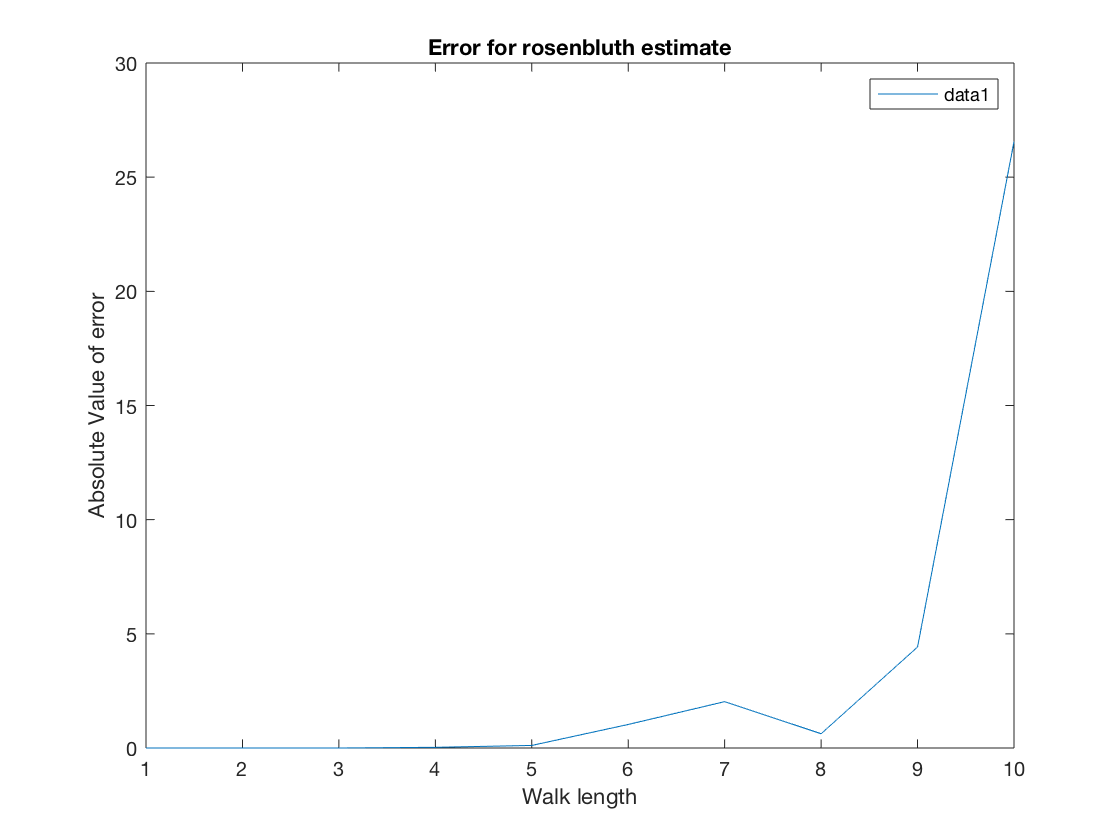

plot(errorforrosenbluth)
title('Error for rosenbluth estimate')
xlabel('Walk length')
ylabel('Absolute Value of error')
legend()

Yes we can estimate the number of self-avoiding walks of length 50. This is possible because we put a limit on the number of directions we can move along at each step by looking at which spaces are unoccupied.

rosenbluthsampling(50,100000)

ans =      5.221923007772319e+21


function estimate = rosenbluthsampling(l, maxsamples)

    % Count of total number of trials performed
    samples = 0; 
    % Since we need the sum of all weights of successful trials, we will
    % store the sum in this variable
    sum = 0;
    
    
    while samples < maxsamples
        
        % Initiate lattice where we perform our walks before every trial to
        % 0. Every time we step to a new coordinate we mark 1.
        lattice = zeros(2*l + 1 ,2*l + 1);
        % Increase trial count by 1
        samples = samples + 1; 
        % Initiate steps performed in walk to 0 before every walk
        n = 0;
        % Start at origin
        x = l+1;
        y = l+1;
        % Mark origin
        lattice(x,y) = 1;
        % Initiate weight to 1 before every trial 
        weight = 1;
        
        % This is the while loop we use to walk around in the lattice. If
        % we reach the required walk length we break out of the loop
        while n < l
            
            % Make a list of the neighbors at every step and update the
            % neighborcount at every step. We first initate these variable 
            % before every step and then we update them
            neighborlist = zeros(4,1);
            % This variable also counts as the atmosphere of the coordinate
            neighorcount = 0;
            
            % When the neighors are unoccupied(== 0), we add them to the
            % list and increase the neighborcount by 1. 
            % We have 'U' for up. It always goes in the first position of
            % neighborlist
            % We have 'D' for down. It always goes in the second position of
            % neighborlist
            % We have 'R' for right. It always goes in the third position of
            % neighborlist
            % We have 'L' for left. It always goes in the fourth position of
            % neighborlist
            if lattice(x+1,y) == 0 
                neighborlist(1) = 'U';
                neighorcount = neighorcount + 1;
            end
            if lattice(x-1,y) == 0 
                neighborlist(2) = 'D';
                neighorcount = neighorcount + 1;
            end
            if lattice(x,y+1) == 0 
                neighborlist(3) = 'R';
                neighorcount = neighorcount + 1;
            end 
            if lattice(x,y-1) == 0 
                neighborlist(4) = 'L';  
                neighorcount = neighorcount + 1;
            end
            
            % When there are no unoccupied neighbors and we haven't
            % completed our walk, we start a new trial
            if neighorcount == 0
                
                break
            
            % Otherwise, we choose an unoccupied neighbor randomly and then
            % move there
            else 
                
                % This is just a technical step. We convert the elements so
                % that they are one of 'U', 'D', 'R', 'L'
                neighborlist = char(neighborlist);
                % We delete the empty places 
                neighborlist = nonzeros(neighborlist);
                % Permutate the list randomly and pick the first element. This is how we choose a random unoccupied neighbor  
                neighborlist = neighborlist(randperm(length(neighborlist)));
                
                % Move to the new position by updating the coordinate
                if neighborlist(1) == 'U'
                    x = x+1;
                end
                if neighborlist(1) == 'D'
                    x = x-1;
                end
                if neighborlist(1) == 'R'
                    y = y+1;
                end
                if neighborlist(1) == 'L'
                    y = y-1;
                end
                
                % Update the new position
                lattice(x,y) = 1;
                % Increase number of steps taken
                n = n+1;
                % Update weight
                weight = weight*neighorcount;
            end
        end
            
        % If a walk is completed i.e. n reaches l, we add the final weight
        % of the walk to the running total
        if n == l
          sum = sum + weight;
        end
    end
    % This is our final estimate!
    estimate = sum/maxsamples;
end